Load Data

clear; clc;


% readtimetable ("Trend Trading Input Output Data.xlsx", "Sheet","Price Data")
priceDS = datastore ("Trend Trading Input Output Data.xlsx","Sheets","Price Data")

priceDS =   SpreadsheetDatastore with properties:

                      Files: {
                             ' ...\Project-Repo-Test\Trend Trading Input Output Data.xlsx'
                             }
                    Folders: {
                             ' ...\kiki.mulyadi\Desktop\Matlab Investment R&D and Live\Project-Repo-Test'
                             }
   AlternateFileSystemRoots: {}
                     Sheets: 'Price Data'
                      Range: ''

  Sheet Format Properties:
             NumHeaderLines: 0
         VariableNamingRule: 'modify'
          ReadVariableNames: true
              VariableNames: {'Time', 'AALI', 'ABBA' ... and 663 more}
              VariableTypes: {'datetime', 'double', 'double' ... and 663 more}

  Properties that control the table returned by preview, <a href

% pricedata.SelectedVariableNames;

% convert ds to tall table
priceTall = tall (priceDS);

% conevrt tall table to tall timetable

priceTall = table2timetable (priceTall);
head (priceTall)

ans =

  8×665 tall timetable

       Time            AALI        ABBA       ABDA       ABMM    ACES    ACST    ADES       ADHI       ADMF    ADMG    ADRO    AGAR    AGII       AGRO       AGRS      AHAP       AIMS      AISA         AKKU       AKPI    AKRA    AKSI    ALDO    ALKA    ALMI    ALTO    AMAG    AMAN    AMAR    AMFG    AMIN

Data cleaning

tic

priceTT = fillmissing (priceTall, 'previous');
priceTT = fillmissing (priceTT, 'next');
priceTT = gather (priceTT);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 3: Completed in 19 sec
- Pass 2 of 3: 0% complete
Evaluation 34% complete


priceTT = 2825×665 timetable
       Time        AALI     ABBA     ABDA     ABMM    ACES     ACST     ADES     ADHI     ADMF    ADMG    ADRO    AGAR    AGII     AGRO     AGRS     AHAP     AIMS     AISA      AKKU     AKPI    AKRA    AKSI     ALDO     ALKA    ALMI     ALTO     AMAG    AMAN    AMAR    AMFG    AMIN    AMOR    AMRT    ANDI    ANJT     ANTM     APEX</

priceTT = tall (priceTT);
head (priceTT)


toc

Elapsed time is 89.356871 seconds.


Cumulative return

cumret = ret2tick (tick2ret (priceTT));
cumret = gather (cumret);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 3: Completed in 0.73 sec
- Pass 2 of 3: Completed in 1.2 sec
- Pass 3 of 3: Completed in 1.6 sec
Evaluation completed in 4.1 sec


cumretvar = cumret.Variables; 
cumretend = cumretvar (end,:);

cumretThreshold = 10;
buyidx = cumretend > cumretThreshold

idx = 1×665 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   1   0   0   1   0   0


cumretendHighValue = cumretend(buyidx)

cumretendHighValue =    32.5386   17.7885   19.3289   58.9595   10.6617   10.1260   11.5385   14.7727   11.1675   22.4762   25.7154   20.7227   12.9032   30.9589   17.8824   18.0000  113.7755   26.9880   13.1956   11.0734   11.6667   11.9608   19.9213   54.0541   11.4516   10.9797   18.3666   22.1217   17.0931   37.2703   16.7407   20.0000   12.0161   16.4667   47.4359   28.0000   34.1880   11.0185   26.3235   38.2166   17.2613   10.4483   18.8000


cumretendHighSymb = cumret.Properties.VariableNames (buyidx)

cumretendHighSymb = 1×43 cell array
    {'ABDA'}    {'AMRT'}    {'ARNA'}    {'ARTO'}    {'BRNA'}    {'CENT'}    {'CLEO'}    {'CPIN'}    {'CSMI'}    {'DCII'}    {'DEFI'}    {'DNET'}    {'EKAD'}    {'EMTK'}    {'ERTX'}    {'GEMA'}    {'GMTD'}    {'INAF'}    {'INDS'}    {'ITMA'}    {'JECC'}    {'JTPE'}    {'KAEF'}    {'KONI'}    {'MAPI'}    {'MARK'}    {'MREI'}    {'MTDL'}    {'MYOR'}    {'PSAB'}    {'PTDU'}    {'PTSP'}    {'SCMA'}    {'SKLT'}    {'SLIS'}    {'STTP'}    {'TCPI'}    {'TECH'}    {'TGKA'}    {'TOWR'}    {'TPIA'}    {'ULTJ'}    {'ZBRA'}



clear cumretvar cumret 


Selected variables

SelectedVarNames = cumretendHighSymb;
SelectedVarNames = sort (SelectedVarNames);
priceSample = priceTT (:, SelectedVarNames);
head (priceSample)

ans =

  8×43 tall timetable

       Time         ABDA     AMRT    ARNA     ARTO     BRNA      CENT     CLEO    CPIN    CSMI    DCII     DEFI      DNET     EKAD     EMTK     ERTX     GEMA    GMTD    INAF     INDS      ITMA     JECC    JTPE    KAEF    KONI    MAPI    MARK     MREI      MTDL      MYOR      PSAB     PTDU    

Build signal

% SMA 30
tic

WindowSize = 30;
priceSample = gather (priceSample);
priceSMA = movavg (priceSample,'simple', WindowSize);
head (priceSMA)

ans = 8×43 timetable
       Time         ABDA      AMRT      ARNA     ARTO     BRNA      CENT     CLEO     CPIN     CSMI    DCII     DEFI      DNET      EKAD      EMTK      ERTX     GEMA    GMTD     INAF      INDS      ITMA      JECC     JTPE     KAEF      KONI      MAPI     MARK     MREI      MTDL      MYOR      PSAB     PTDU    PTSP     SCMA     SKLT    SLIS    STTP 


SMA_Signal = priceSample;
SMA_Signal.Variables = priceSample.Variables > priceSMA.Variables;

toc

Elapsed time is 0.232819 seconds.


Transaction cost adjustment

tic

buyFee = 0.2/100;
sellFee = 0.3/100;

SMASignTemp = SMA_Signal.Variables;
SMA_SignalShiftOneBackward = SMA_Signal;
SMASignShiftTemp = SMA_SignalShiftOneBackward.Variables;

SMASignShiftTemp (1,:) = 0;
SMASignShiftTemp(2:end,:) = SMASignTemp (1:end-1,:);

SMA_Signal.Variables = SMASignTemp;
SMA_SignalShiftOneBackward.Variables = SMASignShiftTemp;

buyidx = SMA_SignalShiftOneBackward.Variables == 0 & SMA_Signal.Variables == 1 ;
buycost = SMA_Signal;
buycost.Variables = buyidx .*(1) .* buyFee;

tail (SMA_Signal);
tail (SMA_SignalShiftOneBackward);
tail (buycost);

sellidx = SMA_SignalShiftOneBackward.Variables == 1 & SMA_Signal.Variables == 0 ;
sellcost = SMA_Signal;
sellcost.Variables = sellidx .* (-1) .* sellFee;

tail (SMA_Signal);
tail (SMA_SignalShiftOneBackward);
tail (sellcost);

transactionCost = SMA_Signal;
transactionCost.Variables = buycost.Variables + sellcost.Variables;

tail (buycost);
tail (sellcost);
tail (transactionCost);

clear SMASignShiftTemp SMASignTemp SMA_SignalShiftOneForward  
clear priceSMA buyidx buycost sellidx sellcost

% SMA_Signal = tall (SMA_Signal); 

toc

Elapsed time is 0.119292 seconds.


Cumret for trading on each symbol 

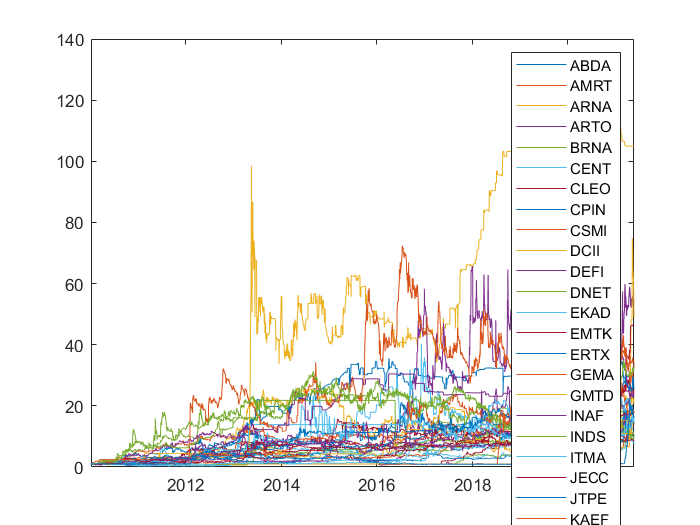

tic

retSym = tick2ret (priceSample);
netretsym = retSym;
transactionCostVariables = transactionCost.Variables;
netretsym.Variables = retSym.Variables + transactionCostVariables(2:end,:);

tail (SMA_Signal);
tail (retSym);
tail (netretsym);

cumretSym = ret2tick (netretsym);

plot (cumretSym.Time, cumretSym.Variables)
legend (cumretSym.Properties.VariableNames)


cumretSym = tall (cumretSym);
retSym = tall (retSym);

clear transactionCost transactionCostVariables

toc

Elapsed time is 0.674298 seconds.


Capital Allocation

dailySignal = priceSample;



save tradingdata.mat 